# **Official Wing Code**

Juan Pablo Meda Castro s3296369

clc;clear;close

## *INPUT SECTION*

# Wing stress

### **Code Input variables**

Wing_length = [0, 0.0228283, 0.0456566, 0.0684848, 0.0913131, 0.114141, 0.13697, 0.159798, 0.182626, 0.205455, 0.228283, 0.251111, 0.273939, 0.296768, 0.319596, 0.342424, 0.365253, 0.388081, 0.410909, 0.433737, 0.456566, 0.479394, 0.502222, 0.525051, 0.547879, 0.570707, 0.593535, 0.616364, 0.639192, 0.66202, 0.684848, 0.707677, 0.730505, 0.753333, 0.776162, 0.79899, 0.821818, 0.844646, 0.867475, 0.890303, 0.913131, 0.93596, 0.958788, 0.981616, 1.00444, 1.02727, 1.0501, 1.07293, 1.09576, 1.11859, 1.14141, 1.16424, 1.18707, 1.2099, 1.23273, 1.25556, 1.27838, 1.30121, 1.32404, 1.34687, 1.3697, 1.39253, 1.41535, 1.43818, 1.46101, 1.48384, 1.50667, 1.52949, 1.55232, 1.57515, 1.59798, 1.62081, 1.64364, 1.66646, 1.68929, 1.71212, 1.73495, 1.75778, 1.78061, 1.80343, 1.82626, 1.84909, 1.87192, 1.89475, 1.91758, 1.9404, 1.96323, 1.98606, 2.00889, 2.03172, 2.05455, 2.07737, 2.1002, 2.12303, 2.14586, 2.16869, 2.19152, 2.21434, 2.23717, 2.26];
Lift = [10.2294, 10.3944, 10.5618, 10.7314, 10.9033, 11.0776, 11.2543, 11.4333, 11.6148, 11.7988, 11.9852, 12.1742, 12.3657, 12.5598, 12.7564, 12.9557, 13.1575, 13.362, 13.5692, 13.779, 13.9915, 14.2066, 14.4244, 14.6449, 14.8681, 15.0939, 15.3223, 15.5534, 15.7871, 16.0232, 16.2619, 16.5031, 16.7466, 16.9924, 17.2405, 17.4907, 17.743, 17.997, 18.2529, 18.5104, 18.7692, 19.0293, 19.2904, 19.5522, 19.8144, 20.0768, 20.3391, 20.6008, 20.8614, 21.1207, 21.378, 21.6329, 21.8847, 22.1328, 22.3765, 22.6149, 22.8473, 23.0727, 23.2901, 23.4985, 23.6966, 23.8831, 24.0569, 24.2164, 24.3598, 24.4857, 24.5923, 24.6775, 24.7394, 24.7757, 24.7844, 24.763, 24.7088, 24.6194, 24.4923, 24.3245, 24.1133, 23.8557, 23.5493, 23.191, 22.7779, 22.3076, 21.7777, 21.186, 20.53, 19.8083, 19.02, 18.1638, 17.2391, 16.2463, 15.1867, 14.0614, 12.8719, 11.6216, 10.3147, 8.95504, 7.54649, 6.09548, 4.60965, 3.09461];
AF_t = linspace(0.153,0.045,100); % Airfoil thickness [m]
S_A = 1.246 * 2; % Surface area of both wings

### Spar material input data

Spar material: Aluminum 2024-T6

E_spar = 72.4e9; % Elastic Modulus skin [Pa]
Ys_spar = 372e6; % Yield Strength skin at 100°C [Pa], at 24°C it is 393 MPa
B_rho = 2780; % Density [kg/m^3]

### Skin material input data

Skin material: Aluminum 2024-T6

E_skin = 72.4e9; % Elastic Modulus skin [Pa]
Ys_skin = 372e6; % Yield Strength skin at 100°C [Pa], at 24°C it is 393 MPa
Skin_rho = 2780; % Density [kg/m^3]

### Ribs input data

Ribs material: Aluminum 2024-T6

Rho_ribs = 2780; % Density [kg/^3]
Rib_t = 0.008; % Ribs thickness [m]

### Spar section 1 dimensions input data

Spar shape: I beam (Wide flange beam)

% Beam 1 dimensions input
Height_Beam_1= 0.08; % Beam height [m]
Width_Beam_1 = 0.025; % Beam width [m]
Web_t_Beam_1= 0.009; % Thickness of the web [m]
Flange_t_Beam_1 = 0.003; % Thickness of the flange [m]

### Reduction factor between spar section 1 and 2 input data

red_factor_1 = 1.4; % Reducing factor between first and second section of the spar
red_factor_2 = 1.37; % Reducing factor between second and third section of the spar

### Maximum safety factor for spar section 1 input data

Sfty_Ftr_Spar = 6.1; % Maximum safety factor in spar section 1

# Skin global buckling

### Skin input data

% Skin dimensions
Skin_L = 0.5; % Length of skin panel, distance between ribs [m]
St = 0.0011; % Skin thickness [m]
Sw = 0.85; % Skin width, airfoil chord at the root [m]

k_Glob_buck = 1; % Global buckling coefficient for a simply supported case (worst case scenario)

### Stringer input data

Stringer shape: T-Section

% Stringer dimensions
Fw = 0.025; % Flange width [m]
Ft = 0.001; % Flange thickness [m]
Wh = 0.029; % Web height [m]
Wt = 0.001; % Web thickness [m]

% Number of stringers
n = 15;

# Skin local buckling

poisson_skin = 0.33; % Poisson ratio aluminum
k_loc_buck = 4; % Buckling coefficient for a/b >= 3

# Fatigue under the wing

n_cycles = 2; % Cycles per flight (1 for take-off and 1 for landing)
D_flights = 5; % Daily flights [day]

# Wings mass

Tap_R = 0.3; % Wing taper ratio

## *CALCULATIONS*

# Wing stress calculation

### Shear force at the root

Shear_Force_root = sum(Lift);

### Beam dimensions

% Beam 1
f_Beam_1 = Height_Beam_1 - 2*Flange_t_Beam_1; % Parameter for calculating the moment of inertia [m]
g_Beam_1 = (Width_Beam_1 - Web_t_Beam_1) / 2; % Parameter for calculating the moment of inertia [m]

c_Beam_1 = Height_Beam_1 / 2; % Distance between neutral axis and top/bottom surface beam [m]

% Beam 2 dimensions
Height_Beam_2= Height_Beam_1 / red_factor_1; % Beam height [m]
Width_Beam_2 = Width_Beam_1 / red_factor_1; % Beam width [m]
Web_t_Beam_2= Web_t_Beam_1 / red_factor_1; % Thickness of the web [m]
Flange_t_Beam_2 = Flange_t_Beam_1 / red_factor_1; % Thickness of the flange [m]

f_Beam_2 = Height_Beam_2 - 2*Flange_t_Beam_2; % Parameter for calculating the moment of inertia [m]
g_Beam_2 = (Width_Beam_2 - Web_t_Beam_2) / 2; % Parameter for calculating the moment of inertia [m]

c_Beam_2 = Height_Beam_2 / 2; % Distance between neutral axis and top/bottom surface beam [m]

% Distance from neutral axis to top skin surface
y_2 = (AF_t / 2); % [m]

% Beam 3 dimensions
Height_Beam_3 = Height_Beam_2 / red_factor_2;
Width_Beam_3 = Width_Beam_2 / red_factor_2;
Web_t_Beam_3= Web_t_Beam_2 / red_factor_2; % Thickness of the web [m]
Flange_t_Beam_3 = Flange_t_Beam_2 / red_factor_2; % Thickness of the flange [m]

f_Beam_3 = Height_Beam_3 - 2*Flange_t_Beam_3; % Parameter for calculating the moment of inertia [m]
g_Beam_3 = (Width_Beam_3 - Web_t_Beam_3) / 2; % Parameter for calculating the moment of inertia [m]

c_Beam_3 = Height_Beam_3 / 2; % Distance between neutral axis and top/bottom surface beam [m]

### Spar Moment of intertia calculation for section 1 and 2

I_spar_1 = (1/12)*(Width_Beam_1)*(Height_Beam_1^3) - 2*(1/12)*(g_Beam_1)*(f_Beam_1^3); % Moment of inertia section 1 [m^4]
I_spar_2 = (1/12)*(Width_Beam_2)*(Height_Beam_2^3) - 2*(1/12)*(g_Beam_2)*(f_Beam_2^3); % Moment of inertia section 2 [m^4]
I_spar_3 = (1/12)*(Width_Beam_3)*(Height_Beam_3^3) - 2*(1/12)*(g_Beam_3)*(f_Beam_3^3); % Moment of inertia section 2 [m^4]

### Moment at any point of the spar calculation

% We obtain a vector of the moment at every point
MM_loop = zeros(size(Wing_length));

for i = 1:length(Wing_length)
    [~, point_index_loop] = min(abs(Wing_length - Wing_length(i)));
    [~, WLS_loop] = size(Wing_length);
    point_loop = WLS_loop - (point_index_loop)+1;
    W_L_loop = Wing_length(1:point_loop);
    New_lift_vector_loop = Lift(point_index_loop:end);

    Mi_loop = (New_lift_vector_loop .* W_L_loop);
    MM_loop(i) = sum(Mi_loop); % Moment at all points in the spar [Nm]
end

### Spar curvature using dimensions of section 1

kk_Spar_1 = MM_loop / (E_spar * I_spar_1); % Spar curvature with section 1 dimensions [m^-1]

### Spar strain and stress using dimensions of section 1

Spar_strain = kk_Spar_1 * c_Beam_1; % Spar strain with section 1 dimensions
Spar_stress = Spar_strain * E_spar; % Spar stress with section 1 dimensions [Pa]

### Skin strain and stress using dimensions of section 1

Skin_strain = kk_Spar_1 .* y_2; % Skin strain with section 1 dimensions
Skin_stress = Skin_strain * E_skin; % Skin stress with section 1 dimensions [Pa]

### Stress difference between spar's yield strength and maximum stress on spar with dimensions of section 1

Stress_difference_1 = (Ys_spar * ones(size(Wing_length))) ./ Spar_stress; % Safety factor at every point in the spar
[~, Sfty_index_1] = min(abs(Stress_difference_1 - Sfty_Ftr_Spar)); % Location index of the point at which safety factor is desired

### Spar curvature using dimensions of section 2, from the point at which safety factor from section 1 is desired

kk_Spar_2 = (MM_loop(Sfty_index_1+1:end)) / (E_spar * I_spar_2); % Spar curvature with section 2 dimensions [m^-1]

### Spar strain and stress of section 2

Spar_2_strain = kk_Spar_2 .* c_Beam_2; % Section 2 spar strain
Spar_2_stress = Spar_2_strain * E_spar; % Section 2 spar stress [Pa]

### Skin strain and stress of section 2

Skin_2_strain = kk_Spar_2 .* (y_2(Sfty_index_1+1:end)); % Skin strain with section 2 dimensions
Skin_2_stress = Skin_2_strain * E_skin; % Skin stress with section 2 dimensions [Pa]

### Final strain and stress with section 1 and 2

% Spar
Spar_1_strain = Spar_strain(1:Sfty_index_1); % Section 1 spar strain
Spar_1_stress = Spar_stress(1:Sfty_index_1); % Section 1 spar stress [Pa]

Total_Spar_strain_1 = horzcat(Spar_1_strain,Spar_2_strain); % Total spar strain 
Total_Spar_stress_1 = horzcat(Spar_1_stress,Spar_2_stress); % Total spar stress [Pa]

% Skin
Skin_1_strain = Skin_strain(1:Sfty_index_1); % Section 1 skin strain
Skin_1_stress = Skin_stress(1:Sfty_index_1); % Section 1 skin stress [Pa]

Total_Skin_strain_1 = horzcat(Skin_1_strain,Skin_2_strain); % Total skin strain
Total_Skin_stress_1 = horzcat(Skin_1_stress,Skin_2_stress); % Total skin stress [Pa]

### Maximum stress at each section and together

% Spar
Max_stress_SP1 = max(Spar_1_stress); % Maximum stress in section 1 [Pa]
Max_stress_SP2_1 = max(Spar_2_stress); % Maximum stress in section 2 [Pa]
Max_stress_SPTotal_1 = max(Total_Spar_stress_1); % Maximum stress in spar [Pa]

% Skin
Max_stress_Skin1 = max(Skin_1_stress);
Max_stress_Skin2_1 = max(Skin_2_stress);
Max_stress_SkinTotal_1 = max(Total_Skin_stress_1);

### Spar length at each section

Length_SP1 = max(Wing_length(1:Sfty_index_1));
Length_SP2 = max(Wing_length(Sfty_index_1+1:end)) - Length_SP1;

### Calculations for third section

Stress_difference_2 = (Ys_spar * ones(size(Spar_2_stress))) ./ Spar_2_stress; % Safety factor at every point in the spar
[~, Sfty_index_2] = min(abs(Stress_difference_2 - Sfty_Ftr_Spar)); % Location

kk_Spar_3 = (MM_loop((Sfty_index_1+Sfty_index_2)+1:end)) / (E_spar * I_spar_3); % Spar curvature with section 3 dimensions [m^-1]

Spar_3_strain = kk_Spar_3 .* c_Beam_3; % Section 3 spar strain
Spar_3_stress = Spar_3_strain * E_spar; % Section 3 spar stress [Pa]

Skin_3_strain = kk_Spar_3 .* (y_2((Sfty_index_1+Sfty_index_2)+1:end)); % Skin strain with section 3 dimensions
Skin_3_stress = Skin_3_strain * E_skin; % Skin stress with section 3 dimensions [Pa]

New_Spar_2_Stress = Spar_2_stress(1:Sfty_index_2);
New_Spar_2_Strain = Spar_2_strain(1:Sfty_index_2);

Total_Spar_strain_2 = horzcat(Spar_1_strain,New_Spar_2_Strain,Spar_3_strain); % Total spar strain 
Total_Spar_stress_2 = horzcat(Spar_1_stress,New_Spar_2_Stress,Spar_3_stress); % Total spar stress [Pa]

New_Skin_2_strain = Skin_2_strain(1:Sfty_index_2); % Section 1 skin strain
New_Skin_2_stress = Skin_2_stress(1:Sfty_index_2); % Section 1 skin stress [Pa]

Total_Skin_strain_2 = horzcat(Skin_1_strain,New_Skin_2_strain,Skin_3_strain); % Total skin strain
Total_Skin_stress_2 = horzcat(Skin_1_stress,New_Skin_2_stress,Skin_3_stress); % Total skin stress [Pa]

Max_stress_SP2_2 = max(New_Spar_2_Stress); % Maximum stress in spar section 2 [Pa]
Max_stress_SP3 = max(Spar_3_stress); % Maximum stress in spar section 3 [Pa]
Max_stress_SPTotal_2 = max(Total_Spar_stress_2); % Maximum stress in spar [Pa]

Max_stress_Skin2_2 = max(New_Skin_2_stress); % Maximum stress in skin section 2 [Pa]
Max_stress_Skin3 = max(Skin_3_stress); % Maximum stress in skin section 3 [Pa]
Max_stress_SkinTotal_2 = max(Total_Skin_stress_2); % Maximum stress in skin [Pa]

New_Length_SP2 = max(Wing_length(Sfty_index_1+1:(Sfty_index_1+Sfty_index_2))) - Length_SP1;
Length_SP3 = max(Wing_length((Sfty_index_1+Sfty_index_2)+1:end)) - New_Length_SP2 - Length_SP1;

Total_Spar_length = Length_SP1 + New_Length_SP2 + Length_SP3;

# Skin global buckling calculation

### Effective length of the skin

Le = Skin_L * k_Glob_buck; % Effective length (distance between ribs) [m]

### Second moment of inertia of cross sectional area including skin and stringers

%Skin area
Askin = St * Sw; % [m^2]

% Stringer area
Astr = (Fw * Ft) + (Wh * Wt); % [m^2]

% Total area
Atotal = Askin + (n * Astr); % Arrange's area [m^2]

% Skin yc centroid
Yc_skin = Wh + Ft + St / 2; % Y coordinate skin centroid

% Stringer yc centroid
Yc_str = (((Wh + Ft) / 2) * (Ft * Fw) + ((Wh^2 * Wt) / 2)) / Astr; % Y coordinate stringer centroid

% Arrange yc centroid
Yc = ((Askin * Yc_skin) + (n * Astr * Yc_str)) / Atotal; % Location of arrange's centroid [m]

% Distance from each figure's centroid to arrange's centroid
dskin = abs(Yc - Yc_skin); % Distance from skin's centroid to arrange's  centroid [m]
dstr = abs(Yc - Yc_str); % Distance from stringer's centroid to arrange's centroid [m]

% Individual figure second moment of inertia calculation

% Skin second moment of inertia [m^4]
Iskin_c = (Sw * St^3) / 12; 
% Stringer second moment of inertia [m^4]
Istr_c = (Wt * Wh * (Yc_str - Wh/2)^2) + (Wt * Wh^3)/12 + (Ft * Fw * (Wh + Ft/2 -Yc_str)^2) + (Fw * Ft^3)/12; 

% Parallel Axis theorem
I_skin = Iskin_c + (Askin * dskin^2); % Skin second moment of inertia about the arrange's neutral axis [m^4]
I_str = Istr_c + (Astr * dstr^2); % Stringer second moment of inertia about the arrange's neutral axis [m^4]

% Total second moment of inertia
I_total = I_skin + (n * I_str); % [m^4]

### Bending rigidity 

% Bending rigidity of the total cross sectional area
B_R = E_skin * I_total; % Bending rigidity [Pa m^4]

### Global critical buckling load on the skin

% Critical load calculation
Pcr_buckling = (pi^2 * B_R) / (Le^2); % Critical load that the skin can withstand without buckling [N]

### Global critical buckling stress on the skin

% Critical stress on the skin
Glob_cr_skin_stress = Pcr_buckling / Atotal;

### Number of ribs

% Number of ribs
n_ribs = ceil(max(Wing_length) / Skin_L); 

% Ribs area (approximated as a rectangular shape)
vector = 1:1:n_ribs;
ribs_f = zeros(size(n_ribs));

for i = 1:n_ribs-1
    a = vector(i) * Skin_L;
    [~, indexx] = min(abs(Wing_length - a));
    ribs_f(i) = Wing_length(indexx);
end

% Airfoil chord
Af_chord = linspace(Sw,(Sw*Tap_R),100);

index_positions = ismember(Wing_length, ribs_f);
rib_index = find(index_positions);
rib_airfoil = AF_t(rib_index); % Rib height [m]
rib_chord = Af_chord(rib_index); % Rib width [m]

% Ribs area
A_ribs = 0.6 * (rib_airfoil .* rib_chord); % [m^2]

% Ribs volume
V_ribs = A_ribs * Rib_t;

% Ribs mass
Ribs_mass = sum(V_ribs * Rho_ribs); % kg

# Skin local buckling calculation

### Distance between stringers

b = (Sw - (n * Fw)) / (n + 1); % Distance between stringers [m]
a2b = Skin_L / b; % a/b ratio

### Local critical buckling stress on the skin

% Critical buckling stress for a skin plate
Loc_cr_skin_stress = ((k_loc_buck * pi^2 * E_skin) / (12 * (1 - poisson_skin^2))) * ((St / b)^2); % [Pa]

# Fatigue under the wing calculation

Approximation using S-N curve for Aluminum 2024-T3

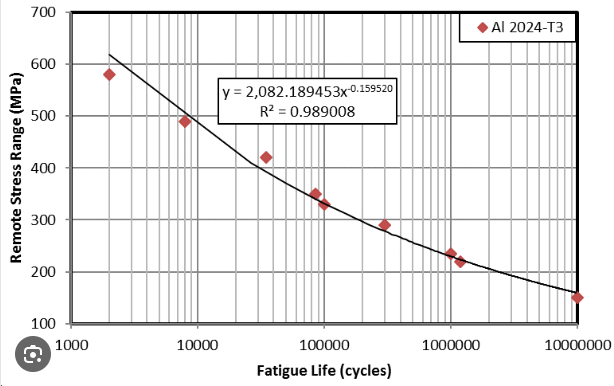

n_year = n_cycles * D_flights * 365; % Total cycles in one year 

Fatigue_load = (Max_stress_SkinTotal_2/(1e6)); % Maximum stress applied in a cyclic way
N_cycles = 1*1e5; % From S-N curve, number of cycles to failure due to fatigue load

Lifetime = N_cycles / n_year; % Total aircraft lifetime [years]

# Wing mass calculation

### Total spar mass

% Spar volume
Spar_1_V = Length_SP1*(2*Flange_t_Beam_1*Width_Beam_1 + Web_t_Beam_1*f_Beam_1); % Section 1 [m^3]
Spar_2_V = New_Length_SP2 * (2*Flange_t_Beam_2*Width_Beam_2 + Web_t_Beam_2*f_Beam_2); % Section 2 [m^3]
Spar_3_V = Length_SP3 * (2*Flange_t_Beam_3*Width_Beam_3 + Web_t_Beam_3*f_Beam_3); % Section 3 [m^3]

% Spar mass
Spar_mass = (Spar_1_V + Spar_2_V + Spar_3_V) * B_rho; % Beam mass [kg]

### Skin Mass and volume

c_root = Sw; % Chord at the root [m]
c_tip = Tap_R * c_root; % Chord at the tip [m]
c_mean_rec = c_root; % Chord length for the rectangular wing
c_mean_tap = (c_root + c_tip) / 2; % Mean chord length for the tapered wing

% Scaling factor between rectangular wing mass and tapered wing mass 
SF = c_mean_tap / c_mean_rec; 

% Upper skin mass
Skin_volume_up = Atotal * max(Wing_length); % Skin volume considering skin and stringers [m^3]
Skin_mass_up = Skin_volume_up * Skin_rho; % Total Skin mass on the upper side of the wing [kg]

% Stringer mass
Stringer_V = Astr * max(Wing_length); % Single stringer volume [m^3]
Stringer_mass = Stringer_V * Skin_rho; % Single stringer mass [kg]
n_low = floor(n/2); % Number of stringers on the lower side of the wing

Skin_V = Askin * max(Wing_length); % Skin volume on the lower side of the wing (without stringers) [m^3]
Skin_mass = Skin_V * Skin_rho; % Skin mass on the lower side of the wing (without stringers) [kg]

% Lower skin mass
Skin_mass_low = Skin_mass + n_low * Stringer_mass; % Total Skin mass on the lower side of the wing [kg]

% Total skin mass of the rectangular wing
Skin_mass_rec = 0.7*(Skin_mass_up + Skin_mass_low); % [kg]

% Total skin mass of the tapered wing
Skin_mass_tap = SF * Skin_mass_rec; % [kg]

### Total wing mass

Wing_mass = Spar_mass + Skin_mass_tap + Ribs_mass; % Total mass of 1 wing [kg]
Both_Wings_mass = Wing_mass * 2; % Total mass of both wings [kg]

### Spar fitting in airfoil

Difference_1 = min(AF_t(1:Sfty_index_1) - Height_Beam_1);
Difference_2 = min(AF_t(Sfty_index_1+1:(Sfty_index_1+Sfty_index_2)) - Height_Beam_2);
Difference_3 = min(AF_t((Sfty_index_1+Sfty_index_2)+1:end) - Height_Beam_3);

## *RESULTS*

# Wing stress

### Maximum stress on spar and skin and comparison with material yield strength

variables_1 = {'Spar yield strength', (Ys_spar / (1e6)), 'MPa';
            'Maximum stress on spar', (Max_stress_SPTotal_2/(1e6)), 'MPa';
            'Safety Factor',(Ys_spar/Max_stress_SPTotal_2),'MPa';
            'Skin yield strength', (Ys_skin /(1e6)), 'MPa';
            'Maximum stress on skin', (Max_stress_SkinTotal_2/(1e6)), 'MPa';
            'Safety Factor', (Ys_spar/Max_stress_SkinTotal_2), 'MPa'};
disp(variables_1)

    {'Spar yield strength'   }    {[     372]}    {'MPa'}
    {'Maximum stress on spar'}    {[160.6186]}    {'MPa'}
    {'Safety Factor'         }    {[  2.3160]}    {'MPa'}
    {'Skin yield strength'   }    {[     372]}    {'MPa'}
    {'Maximum stress on skin'}    {[308.7408]}    {'MPa'}
    {'Safety Factor'         }    {[  1.2049]}    {'MPa'}



### Maximum stresses on spar and skin, on each section

variables_2 = {'Maximum stress Spar section 1', (Max_stress_SP1 / (1e6)), 'MPa';
            'Maximum stress Spar section 2', (Max_stress_SP2_2/(1e6)), 'MPa';
            'Maximum stress Spar section 3', (Max_stress_SP3/(1e6)), 'MPa';
            'Maximum stress Skin section 1', (Max_stress_Skin1 /(1e6)), 'MPa';
            'Maximum stress Skin section 2', (Max_stress_Skin2_2/(1e6)), 'MPa';
            'Maximum stress Skin section 3', (Max_stress_Skin3/(1e6)), 'MPa';};
disp(variables_2)

    {'Maximum stress Spar section 1'}    {[160.6186]}    {'MPa'}
    {'Maximum stress Spar section 2'}    {[159.7248]}    {'MPa'}
    {'Maximum stress Spar section 3'}    {[144.5786]}    {'MPa'}
    {'Maximum stress Skin section 1'}    {[307.1830]}    {'MPa'}
    {'Maximum stress Skin section 2'}    {[308.7408]}    {'MPa'}
    {'Maximum stress Skin section 3'}    {[299.6749]}    {'MPa'}



### Spar length of each section

variables_3 = {'Section 1 of the spar length', (Length_SP1), 'm';
            'Section 2 of the spar length', (New_Length_SP2), 'm';
            'Section 3 of the spar length', (Length_SP3), 'm';
            'Total spar length', (Total_Spar_length), 'm'};
disp(variables_3)

    {'Section 1 of the spar length'}    {[0.8675]}    {'m'}
    {'Section 2 of the spar length'}    {[0.5022]}    {'m'}
    {'Section 3 of the spar length'}    {[0.8903]}    {'m'}
    {'Total spar length'           }    {[2.2600]}    {'m'}



# Skin global buckling

### Global critical buckling load and stress

variables_4 = {'Skin global critical buckling load', (Pcr_buckling/(1e3)), 'kN';
               'Skin global critical buckling stress', (Glob_cr_skin_stress/(1e6)), 'MPa';
               'Maximum stress on skin', (Max_stress_SkinTotal_2/(1e6)), 'MPa';
               'Safety factor', (Glob_cr_skin_stress/Max_stress_SkinTotal_2),'MPa'};
disp(variables_4)

    {'Skin global critical buckling load'  }    {[631.7470]}    {'kN' }
    {'Skin global critical buckling stress'}    {[362.0326]}    {'MPa'}
    {'Maximum stress on skin'              }    {[308.7408]}    {'MPa'}
    {'Safety factor'                       }    {[  1.1726]}    {'MPa'}



# Skin local buckling

### Local critical buckling stress

variables_5 = {'Skin local critical buckling stress', (Loc_cr_skin_stress/(1e6)), 'MPa';
               'Maximum stress on skin', (Max_stress_SkinTotal_2/(1e6)), 'MPa';
               'Safety Factor', (Loc_cr_skin_stress/Max_stress_SkinTotal_2),'MPa'};
disp(variables_5)

    {'Skin local critical buckling stress'}    {[366.9685]}    {'MPa'}
    {'Maximum stress on skin'             }    {[308.7408]}    {'MPa'}
    {'Safety Factor'                      }    {[  1.1886]}    {'MPa'}



# Fatigue

variables_6 = {'Wings lifetime', (Lifetime), 'Years'};
disp(variables_6)

    {'Wings lifetime'}    {[27.3973]}    {'Years'}



# Plots

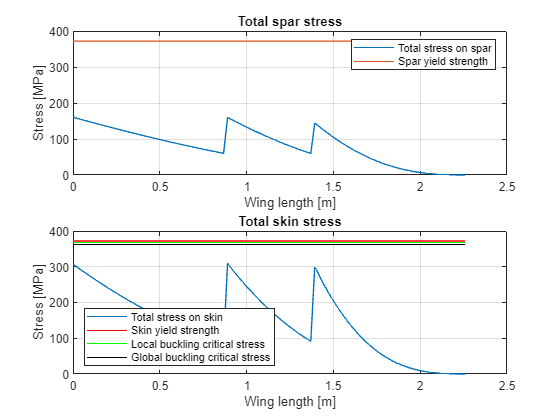

figure(1)
subplot(2,1,1)
plot(Wing_length,(Total_Spar_stress_2 / (1e6)))
title('Total spar stress')
xlabel('Wing length [m]')
ylabel('Stress [MPa]')
hold on
plot(Wing_length,((Ys_spar * ones(size(Wing_length)))/(1e6)))
legend('Total stress on spar', 'Spar yield strength')
grid on
hold off

subplot(2,1,2)
plot(Wing_length,(Total_Skin_stress_2 / (1e6)),'DisplayName','Total stress on skin')
title('Total skin stress')
xlabel('Wing length [m]')
ylabel('Stress [MPa]')
hold on
plot(Wing_length,((Ys_skin * ones(size(Wing_length)))/(1e6)),'r', 'DisplayName','Skin yield strength')
plot(Wing_length,((Loc_cr_skin_stress * ones(size(Wing_length)))/(1e6)), 'g','DisplayName','Local buckling critical stress')
plot(Wing_length,((Glob_cr_skin_stress * ones(size(Wing_length)))/(1e6)), 'k','DisplayName','Global buckling critical stress')
legend('show','Location','southwest')
grid on
hold off

disp(['Maximum strain in spar: ', num2str(max(Total_Spar_strain_2)), ' [m/m]' ])

Maximum strain in spar: 0.0022185 [m/m]


disp(['Maximum strain in skin: ', num2str(max(Total_Skin_strain_2)), ' [m/m]' ])

Maximum strain in skin: 0.0042644 [m/m]


# Wing mass

variables_7 = {'Upper side skin mass', (Skin_mass_up), 'kg';
               'Lower side skin mass', (Skin_mass_low), 'kg';
               'Total skin mass', (Skin_mass_tap), 'kg';
               'Spar mass', (Spar_mass), 'kg';
               'Ribs mass', (Ribs_mass), 'kg';
               'Single wing mass', (Wing_mass), 'kg';
               'Both wings mass', (Both_Wings_mass), 'kg'};
disp(variables_7)

    {'Upper side skin mass'}    {[10.9635]}    {'kg'}
    {'Lower side skin mass'}    {[ 8.2493]}    {'kg'}
    {'Total skin mass'     }    {[ 8.7418]}    {'kg'}
    {'Spar mass'           }    {[ 3.0981]}    {'kg'}
    {'Ribs mass'           }    {[ 2.7902]}    {'kg'}
    {'Single wing mass'    }    {[14.6302]}    {'kg'}
    {'Both wings mass'     }    {[29.2604]}    {'kg'}

